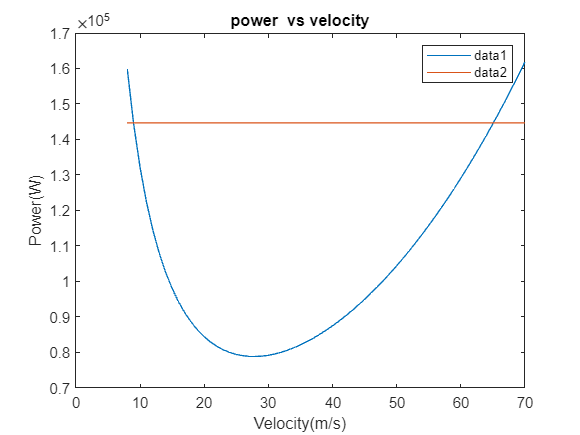

clear all;
%propeller engine with single IC engine

%Given data of aircraft
W=12900; % weight of the aircraft with fuel(N)
Gamma=5;
S=16.26;%Wing planform area(m^2)
AR=7.4; %Aspect Ratio
CL_max=2.4;
Alpha_stall=19.8;
Pa_max=216250; %maximum available thrust at sea level from both engine
CD0 = 0.026; %parasite drag coefficient
K=0.054;

% W_f=168*9.81; %fuel weight
% TSFC=2.7/3600; %kg/W-s
% n_max=2; %maximum load factor
% CL=0.02+0.12*Alpha;
% CD=0.026+0.054*CL^2;
% CM=0.12-0.18*Alpha+0.075*del_e;
Pi=1; % considering maximum power setting

% Minimum Thrust required at 3000m corresponding velocity,AOA and elevator deflection
% Calling density from function ISA_AFM which is 

height = 3;
atmosphere_data = atm_table(height);

% Extracting density values from the atmospheric data
V = 30:0.01:300;
rho_3=atmosphere_data(height+1,5); %density at 3000 m

% CL_md=sqrt(CD_0/K); % CL for min drag
% E_max=CL_md/(2*CD_0);%  max CL/CD for TR_min
% V_md=sqrt(2*W/(Rho_3*S*CL_md));
% TR_min=W/E_max;
% AOA_CL_Vmd=(CL_md-0.02)/0.12;
% del_e_Vmd=(0.18*AOA_CL_Vmd-0.24)/0.28;

P_eff=0.8;
Pa_max_3=P_eff*Pi*((rho_3/1.225)^0.6)*Pa_max; % maximum available thrust at 3000m

%Calculatimg Minimum power required velocity and corresponding AOA and Elevator deflection

CL_mp=sqrt(3*CD0/K);
V_mp=sqrt(2*W*cosd(Gamma)/(rho_3*S*CL_mp));
PR_min=((0.5*rho_3*(V_mp^3)*S*CD0)+((2*K*(W*cosd(Gamma))^2)/(rho_3*S*V_mp)))+(W*sind(Gamma)*V_mp);
AOA_Vmp=(CL_mp-0.02)/0.12;
del_e_Vmp=(0.08*AOA_Vmp-0.12)/0.075;

% maximum velocity and minimum velocity
%A,B,C,D,E are coefficient of  polynomial equation(P) of 4th power
A=0.5*rho_3*S*CD0;
B=0;
C=W*sind(Gamma);
D=-Pa_max_3;
E=(2*K*(W*cosd(Gamma))^2)/(rho_3*S);
P=[A B C D E];
V_M_3=roots(P);
V_max_3=V_M_3(3);
V_min_3=V_M_3(4);
  
% AOA and elevator deflection for Maximum and minimum velocity

CL_Vmin_3=2*W*cosd(Gamma)/(rho_3*S*(V_min_3)^2);
AOA_Vmin=(CL_Vmin_3-0.02)/0.12;
del_e_Vmin=(0.08*AOA_Vmin-0.12)/0.075;

CL_Vmax_3=2*W*cosd(Gamma)/(rho_3*S*(V_max_3)^2);
AOA_Vmax=(CL_Vmax_3-0.02)/0.12;
del_e_Vmax=(0.08*AOA_Vmax-0.12)/0.075;

%calculating stall velocity
V_stall=sqrt(2*W*cosd(Gamma)/(rho_3*S*CL_max));
AOA_Vstall=(CL_max-0.02)/0.12;

%Power vs velocity curve at 3 km
PR=zeros;
PA=zeros;
P_min=zeros;
D_r=zeros;
V= 8:1:70;
for i=1:length(V)
 
 PR(i)=((0.5*rho_3*(V(i)^3)*S*CD0)+((2*K*(W*cosd(Gamma))^2))/(rho_3*S*V(i)))+(W*sind(Gamma)*V(i));
 PA(i)=Pa_max_3;
 P_min(i)=PR_min;
end


plot(V, PR);
hold on;
plot(V, PA);
hold off;


xlabel('Velocity(m/s)');
ylabel('Power(W)');
legend('show');
title('power  vs velocity');


Rho_h=zeros;
Pa_max_h=zeros;
A_h=zeros;
B_h=zeros;
C_h=zeros;
D_h=zeros;
E_h=zeros;
P_h=zeros;
V_M_h=zeros;
V_max_h=zeros;
V_min_h=zeros;
V_stall_h=zeros;

%Flight envelop
 h=0:1:10;

 for i=1:length(h)
    x = atm_table(i);
    Rho_h(i)=x(i,5);
    Pa_max_h(i)=P_eff*Pi*((Rho_h(i)/1.225)^0.6)*Pa_max;
    A_h =0.5*Rho_h(i)*S*CD0;
    B_h=0;
    C_h=W*sind(Gamma);
    D_h =-Pa_max_h(i);
    E_h =(2*K*(W*cosd(Gamma))^2)/(Rho_h(i)*S);
    P_h =[A_h B_h C_h D_h E_h];
    V_M_h=roots(P_h);
    V_max_h(i)=V_M_h(3);
    V_min_h(i)=V_M_h(4);
    V_stall_h(i)=sqrt(2*W*cosd(Gamma)/(Rho_h(i)*S*CL_max));
 end

plot(V_max_h,h)

hold on 
plot(V_min_h,h)

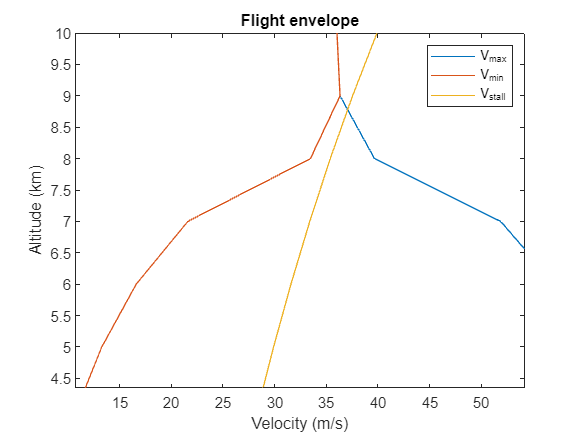

hold on 
plot(V_stall_h,h)
hold off

% Set labels and legend for altitude plot
xlabel('Velocity (m/s)');
ylabel('Altitude (km)');
legend('V_{max}', 'V_{min}', 'V_{stall}');
title('Flight envelope');

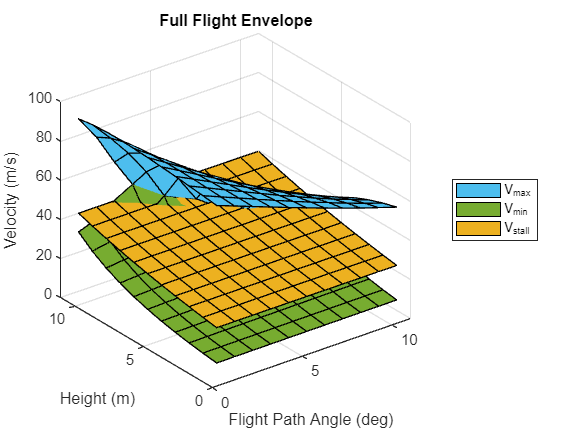

Gamma=0:1:10;
for j=1:length(Gamma)
 for i=1:length(h)
    x = atm_table(i);
    Rho_h(i)=x(i,5);
    Pa_max_h(i)=P_eff*Pi*((Rho_h(i)/1.225)^0.6)*Pa_max;
    A_h =0.5*Rho_h(i)*S*CD0;
    B_h=0;
    C_h=W*sind(Gamma(j));
    D_h =-Pa_max_h(i);
    E_h =(2*K*(W*cosd(Gamma(j)))^2)/(Rho_h(i)*S);
    P_h =[A_h B_h C_h D_h E_h];
    V_M_h=roots(P_h);
    V_max_h(i,j)=real(V_M_h(3));
    V_min_h(i,j)=real(V_M_h(4));
    V_stall_h(i,j)=sqrt(2*W*cosd(Gamma(j))/(Rho_h(i)*S*CL_max));
 end
end
figure
surf(V_max_h,'FaceColor','#4DBEEE')
hold on
surf(V_min_h,'FaceColor','#77AC30')
hold on
surf(V_stall_h,'FaceColor','#EDB120')
hold off

xlabel('Flight Path Angle (deg)');
ylabel('Height (m)');
zlabel('Velocity (m/s)');
title('Full Flight Envelope');

% Add a color legend
legend({'V_{max}', 'V_{min}', 'V_{stall}'}, 'Location', 'eastoutside');

% Customize the view angle
view(3); % 3D view